Search for each and every functions in matlab documentation & related stuff on internet..

# **Task 1:**

**Defining initial parameters **

xTorso = 0.12; % x distance from body to foot 
g = 9.807; 
Ts = 0.005; %sample time (s)
zRobot = 0.78;%The height of the robot when standing straight is defined as zRobot.
zModel = 0.68;%The height of the pendulum (and hence the height at which we will make the robot walk at) is defined by zModel.    
swingHeight = 0.1; 

x0 = 0.12; %initial x position of COM
dx0 = -0.4501; %initial velocity in x direction of COM
y0 = -0.1; %initial y position of COM
dy0 = 0.3845;%initial velocity in y direction of COM

Create a discrete state-space model of the linear inverted pendulum

A = [0   1 0    0
    g/zModel 0 0    0
    0    0 0    1
    0    0 g/zModel 0]; 
B = [0 0
     1 0
     0 0
     0 1]; 
C = [1 0 0 0
     0 0 1 0]; 
D = [0 0;0 0]; 

lipm = ss(A,B,C,D); 
lipmD = c2d(lipm, Ts); 

Ad = lipmD.A; 
Bd = lipmD.B;
Cd = lipmD.C;
Dd = lipmD.D;

The initial state `state0` is the initial condition that allows a symmetric trajectory

state0 = [x0; dx0; y0; dy0];

We want to look at the LIPM's natural dynamics, so the system is not actuated. Hence the input vector `u0` is all zeros.

u0 = [0; 0];

Similarly, create a `simStates` structure to keep track of the simulation information and pass it to other functions.

simStates = struct('bodyPos',[],'footPos',[],'timeVec',[]);

This assignment assumes the robot makes the left step first. The first two entries below define the starting position of both left and right feet, at offsets of `-xTorso` and `+xTorso`, respectively. Then, the third entry of `footPos` will be for the left foot first, the fourth for the right foot, and so on. Change accordingly depending on which foot is going out first and also which direction it is headed.

robotpos0 = [0; 0; zRobot]; 


% Store left and right foothold position (left:odd, right:even)
%Place your code here
simStates.footPos(:,end+1) = ; % left foot
simStates.footPos(:,end+1) = ; % right foot
%Place your code here


% Set the total number of steps to take
numSteps = 10; %any number 

Initializing graphics objects help us animate the model. 

hFig = figure; 
hFig.Visible = 'on'; % for livescript 
hFig.Units = 'Normalized'; 
hFig.OuterPosition = [0 0 1 1]; 
hAx  = axes(hFig); 

% create handles for plots 
hold(hAx, 'on'); 
hLeg  = plot3(hAx,[0,robotpos0(1)],[0,robotpos0(2)],[0,robotpos0(3)],...
                '-o','MarkerIndices',2,'LineWidth',2,'MarkerSize',8); % represents com + leg 
hCom = plot3(hAx,robotpos0(1),robotpos0(2),robotpos0(3)); % represents com traj

hLineFootHold = plot3(hAx, simStates.footPos(1,:), simStates.footPos(2,:), simStates.footPos(3,:)); % represents foothold traj


%Place your code here
% Use simstates to give parameters to function for plotting
hLineLeftFoot = ;
hLineRightFoot =;
%Place your code here


hold(hAx, 'off'); 

grid(hAx, 'on'); 
view(hAx,3)
axis equal 
hAx.XLim = [-3*zRobot 3*zRobot];
hAx.YLim = [-3*zRobot 3*zRobot]; 
legend(hAx, 'Virtual Leg and COM of LIP','Trajectory of COM', 'Foot Hold', 'Left Foot', 'Right Foot', ...
       'Location', 'northeast');

## Simulation

### Move the COM above one foot

This script is used to create a Center of Mass (COM) and swing foot trajectory for the robot to follow. 

First we have to lower the body and go to initial condition (`x0`, `y0`, `dx0`, `dy0`). And move after that. 

Use [`cubicpolytraj`](https://www.mathworks.com/help/robotics/ref/cubicpolytraj.html)` function to execute motion.` 

The variable `walkRdyPoints` has a hardcoded value. We command the robot to lower its body and at the same time move toward the right foot because it will be standing on the right foot during task 2.

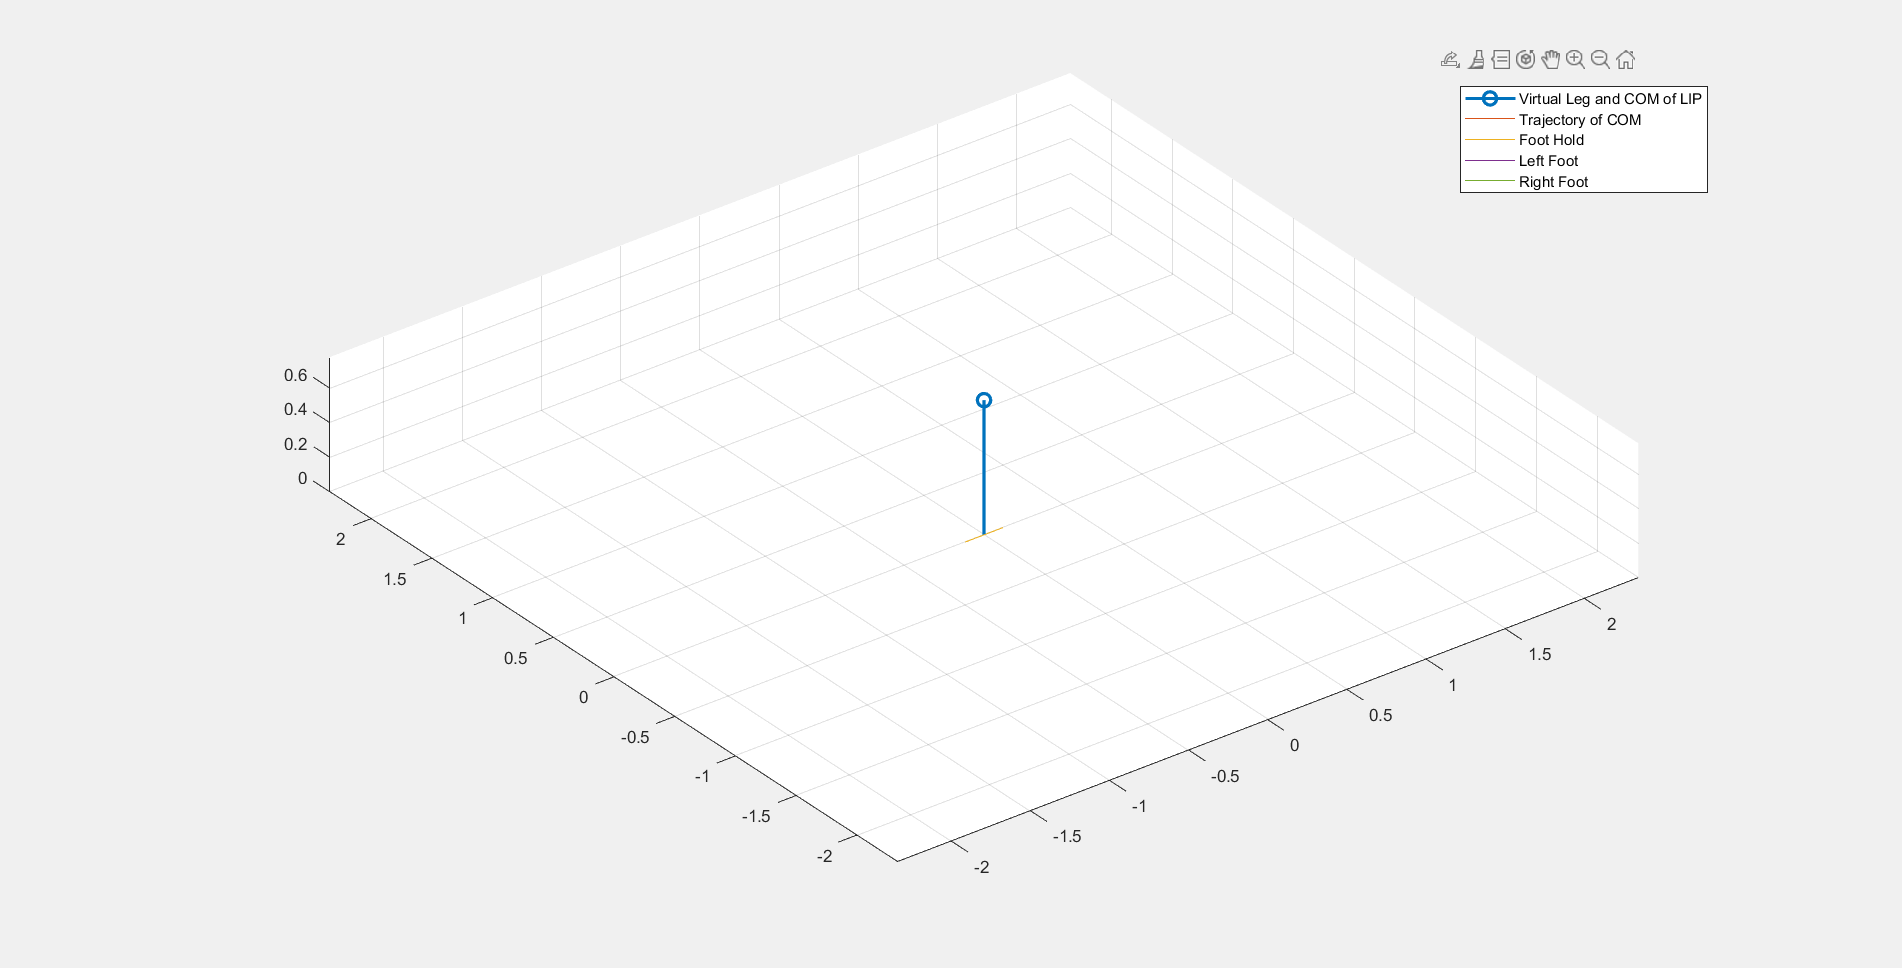

Unrecognized function or variable 'animateOn'.

walkRdyPoints = [0      0.67*x0;   %%hardcoding the distance of foot from com
                 0      0      ; 
                 zRobot zModel];  
% Note: We are moving COM to be partly over the right foot

timepoints = [0 1]; % Hard-coded 1 second to move down
timevec = timepoints(1):Ts:timepoints(end)-Ts; 
[q, qd] = cubicpolytraj(walkRdyPoints, timepoints, timevec);  %U have to pass parameters to cubicpolytaj
simStates.bodyPos = [simStates.bodyPos q]; 
simStates.timeVec = [simStates.timeVec timevec]; 

% save data
fhold_x = simStates.footPos(1,1); 
fhold_y = simStates.footPos(2,1); 
stepinfo.index = 1; 


%Place your code here
bodystate = ;  % pos wrt world(Use the position & velocity of cubicpolytraj here)
%Place your code here


relstate = bodystate - [fhold_x; 0; fhold_y; 0; 0; 0]; % save pos wrt foot  
stepinfo.state = relstate;
stepinfo.timevec = timevec; 
stepinfo.mode = 'doublesupport'; 
stepinfo.footplant = [fhold_x; fhold_y; 0]; % state is in absolute position 
stepinfos{1} = stepinfo; 

% update graphics
for idx = 1:size(simStates.bodyPos,2)                        
    points = [zeros(3,1) simStates.bodyPos(:,idx)];        %changing position according to current time point


    %Place your code here
                                   %Use helper function to
                                   % plot the initial step                                                               
    %Place your code here
    if animateOn
        pause(0.005);
    end
end

## **After completing you would be able to vizualize the position of bot before moving to initial condition.**

#### **Some helper functions(which u will need)**

Adds points to a graphics line object..

function appendLine(gHandle, points)
    gHandle.XData(end+1) = points(1); 
    gHandle.YData(end+1) = points(2); 
    gHandle.ZData(end+1) = points(3); 
end

Replaces points in a graphics line object..

function updateLine(gHandle, points)
    gHandle.XData = points(1,:); 
    gHandle.YData = points(2,:); 
    gHandle.ZData = points(3,:); 
end